# **Esercitazione 1 - ECG**

Obiettivo 1: implementare una funzione per identificare i picchi R all'interno di ciascun segnale.

Caricamento del dato nel workspace utilizzando la funzione `load().`

load("data.mat")

Suddivisione del segnale in finestre continue con stessa lunghezza pari a pochi secondi (scelti arbitrareamente) e quindi rimozione del trend lineare tramite l'uso della funzione detrend.

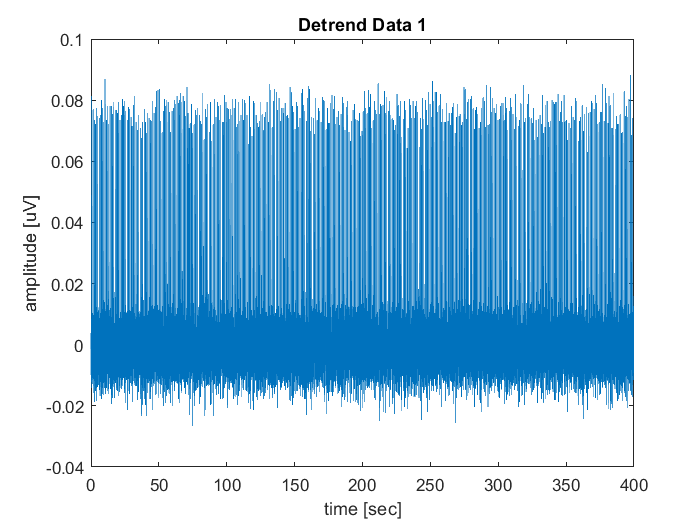

%lunghezza k delle finestre 
k = 1; % [s]

%suddivisione dei segnali
data1 = reshape(data1,fs*k,[]);
data1NoTrend = detrend(data1);

data2 = reshape(data2,fs*k,[]);
data2NoTrend = detrend(data2);

%visualizzazione del risultato ottenuto
data1NoTrend = data1NoTrend(:);

data2NoTrend = data2NoTrend(:);

drawPlot(time, data1NoTrend, 'Detrend Data 1')

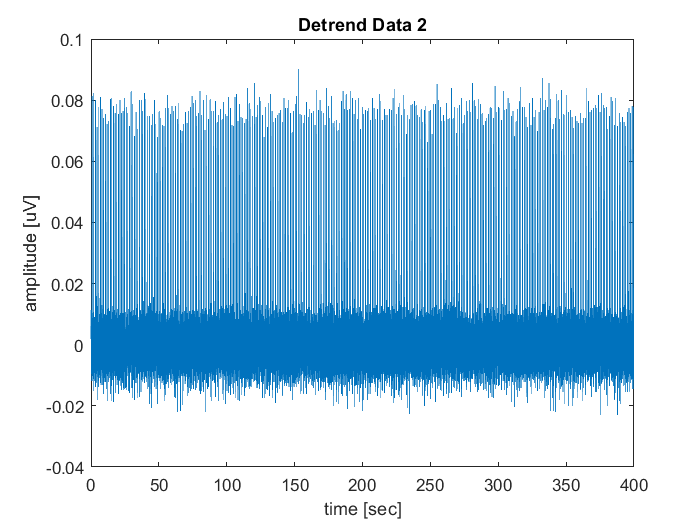

drawPlot(time, data2NoTrend, 'Detrend Data 2')

Identificazione picchi R tramite una soglia ottima.

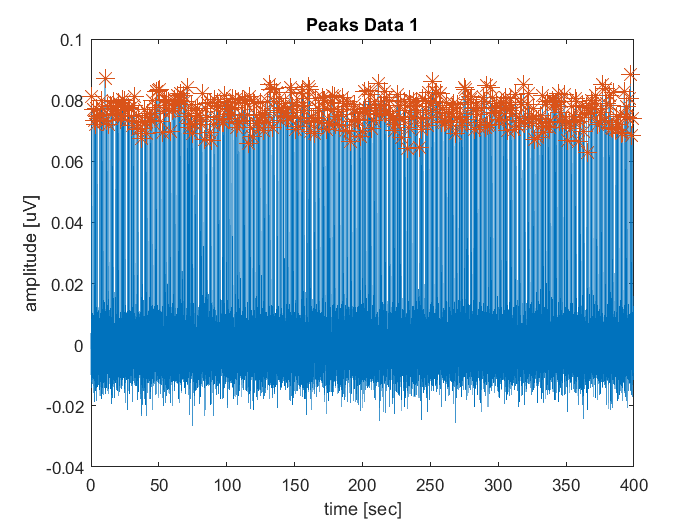

%Utilizzo funzione per il calcolo della soglia ottima
%thr=find_thr(data1NoTrend,6);
%[values1,MaxInd1] = findpeaks(data1NoTrend,fs,'MinPeakHeight',  thr);
[values1, MaxInd1] = find_ecg_peaks(data1NoTrend, fs,6);

drawPlot(time, data1NoTrend, 'Peaks Data 1')

hold on
plot(MaxInd1,values1,'*','MarkerSize',10)
hold off

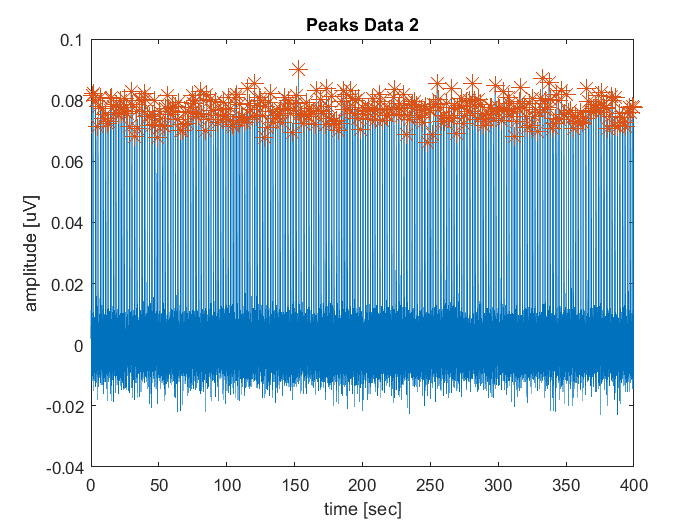

% thr=find_thr(data2NoTrend,6);
% [values2,MaxInd2] = findpeaks(data2NoTrend,fs,'MinPeakHeight',  thr);
[values1, MaxInd2] = find_ecg_peaks(data2NoTrend,fs,6);

drawPlot(time, data2NoTrend, 'Peaks Data 2')

hold on
plot(MaxInd2,values2,'*','MarkerSize',10)
hold off

Obiettivo 2: implementare una funzione compute_heart_rate per stimare la frequenza del battito cardiaco.

heart_rate1 = compute_heart_rate ( MaxInd1,data1NoTrend,fs)

heart_rate1 = 64.9500

heart_rate2 = compute_heart_rate ( MaxInd2,data2NoTrend,fs)

heart_rate2 = 49.8000

Obiettivo 3: implementare una funzione per il calcolo della durata del complezzo QRS e per la visualizzazione del complesso QRS medio.

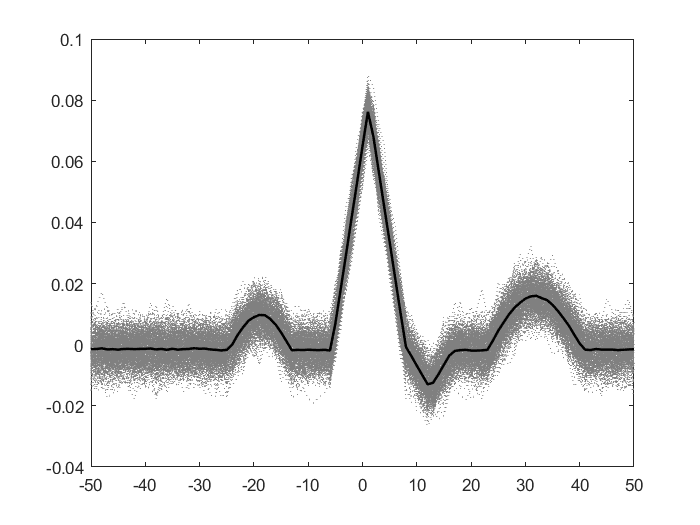

% calcolo distanza tra picchi R successivi
dist_RR1=MaxInd1(2:end)-MaxInd1(1:end-1);
dist_RR2=MaxInd2(2:end)-MaxInd2(1:end-1);

%calcolo distanza media tra picchi R successivi per il tracciato 1 
dist_media1=round(mean(dist_RR1));

%considero una distanza inferiore
meta_dist1=dist_media1/20;

%costruisco l'asse del tempo per il tracciato 1 
asse_tempo=linspace( -1000 * meta_dist1 ,  1000 * meta_dist1 , 1000* 2*meta_dist1 + 1);


%matrice che contiene i singoli tracciati [numero campioni x numero battiti]
figure 
solo_tracciato1=zeros(length(MaxInd1), fs*meta_dist1*2 +1);

for j=1:length(MaxInd1)
    solo_tracciato1(j,:)=data1NoTrend( fs*(MaxInd1(j)-meta_dist1) : fs*(MaxInd1(j)+meta_dist1));
    
    plot(  asse_tempo , solo_tracciato1(j,:) , ":" , "Color",'#808080')
    hold on
end

%tracciato complesso medio
solo_medio1=mean(solo_tracciato1);

hold on
plot( asse_tempo , solo_medio1, "k", "LineWidth", 1.5);
hold off

%calcolo durata del complesso qrs
% qrs_duration (solo_tracciato1);
qrs_medio1 = mean (qrs_duration (solo_tracciato1))

qrs_medio1 = 18.1339

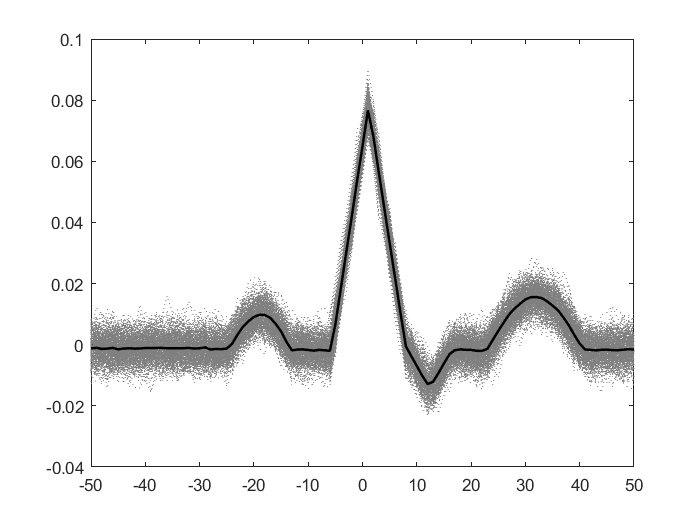

% solo_tracciato1=solo_tracciato1';
% solo_medio1=mean(solo_tracciato1);
% 
% plot(solo_medio1, "k", "LineWidth", 1.5);
% hold off

%calcolo distanza media tra picchi R successivi per il tracciato 2
dist_media2=round(mean(dist_RR2));

%considero una distanza inferiore
meta_dist2=dist_media2/20;

%costruisco l'asse del tempo per il tracciato 2
asse_tempo=linspace( -1000 * meta_dist2 ,  1000 * meta_dist2 , 1000* 2*meta_dist2 + 1);

figure 
solo_tracciato2=zeros(length(MaxInd2), fs* meta_dist2*2 +1);

for j=1:length(MaxInd2)
    solo_tracciato2(j,:)=data2NoTrend(fs*(MaxInd2(j)-meta_dist2) : fs*(MaxInd2(j)+meta_dist2));
    
    plot( asse_tempo, solo_tracciato2(j,:) , ":" , "Color",'#808080')
    hold on
end

solo_medio2=mean(solo_tracciato2);

hold on
plot(asse_tempo, solo_medio2, "k", "LineWidth", 1.5);
hold off

%calcolo durata complesso QRS
% qrs_duration (solo_tracciato2);
qrs_medio2= mean (qrs_duration (solo_tracciato2))

qrs_medio2 = 18.2470

Obiettivo 4: implementare una funzione per la stima della densità di probabilità delle variabili derivate da ECG per descrivere i ritmi cardiaci.

%istogramma RR interval tracciato 1

% mu_RR1 = mean (dist_RR1);
% sigma_RR1 = var (dist_RR1);
% 
% %norm1 = mu_RR1 + randn(1, length(dist_RR1) ) *sigma_RR1;
% 
% %istogramma RR interval tracciato 2
% 
% mu_RR2 = mean (dist_RR2);
% sigma_RR2 = var (dist_RR2);

%norm2 = mu_RR2 + randn(1, length(dist_RR2) ) *sigma_RR2;


% 
% gm = gmdistribution (mu_RR2, sigma_RR2);
% norm2= pdf(gm, length(dist_RR2));

% figure
% plot(gm)

n_bins = 100; 

bin_edges = linspace(min([dist_RR1 ; dist_RR2]),max([dist_RR1 ; dist_RR2]), n_bins+1);

bin_centers = zeros(n_bins,1);
    
for idx = 1:n_bins
    bin_centers(idx) = (bin_edges(idx+1)+bin_edges(idx))/2;
end

figure
histogram(dist_RR1 , bin_centers)
hold on
histogram(dist_RR2 , bin_centers)
hold off

histogram(dist_RR1 , 100)

histogram(dist_RR1 , 10)







n_bins = 20; 

qrs1=qrs_duration (solo_tracciato1);
qrs2=qrs_duration (solo_tracciato2);

histogram(qrs1)
histogram(qrs2)


bin_edges = linspace(min([qrs1 , qrs2]),max([qrs1 , qrs2]), n_bins+1);

bin_centers = zeros(n_bins,1);
    
for idx = 1:n_bins
    bin_centers(idx) = (bin_edges(idx+1)+bin_edges(idx))/2;
end

histogram(qrs1 , bin_centers)
histogram(qrs2 , bin_centers)


figure
histogram(qrs1 , bin_centers)
hold on
histogram(qrs2 , bin_centers)




Istogramma delle variabili derivate dall'ECG per entrambi i ritmi cardiaci.